## `Materials`

`See code`

g10_800um = Material('Garolite', 2000, 283000000, 0.0008); %https://www.insulcut.com.au/nema-g-1011-fiberglass-epoxy-laminate/
lwasa_800um =  Material('ASA Aero 2wall', 990, 28000000, 0.0008); %https://colorfabb.com/data-sheets#BKO0CIF
lwasa_400um =  Material('ASA Aero', 990, 28000000, 0.0004); %https://colorfabb.com/data-sheets#BKO0CIF
asa_800um =  Material('ASA', 1050, 34000000, 0.0008); %https://colorfabb.com/data-sheets#BKO0CIF
cf_600um = Material('Carbon Fibre', 2000, 5000000000, 0.0006); % Cant find good source
al_6063 =   Material('Aluminium', 2700, 60000000, 0.012); % varies by temper - https://atlassteels.com.au/wp-content/uploads/2021/08/Aluminium-Alloy-6063-Data-Sheet-11-08-21.pdf
foam_5mm =  Material('Foam', 0.254/(0.841*0.594*0.005), 9000000, 0.005); %https://www.officeworks.com.au/shop/officeworks/p/a1-foam-board-5mm-black-ljpcfba1bk
foam_2mm =  Material('Foam', 0.254/(0.841*0.594*0.005), 9000000, 0.002); %guess

structure = g10_800um;
heavyPrint = lwasa_800um;
lightPrint = lwasa_400um;
boomMaterial = cf_600um;
metal = al_6063;

## Estimation

Properties Are: [Mass m (kg), Center of Gravity x (m), Rotational Inertia Iyy (kgm^2)]

### Wing

a = Aircraft();

% Wing

wingSpan = 2.5;
aspectRatio = 8;

chord = wingSpan/aspectRatio

chord = 0.3125


wingLeadingX = 0.25 * chord;
wingFrontSparX = 0; % Origin at 25% of chord
wingBackSparX = wingLeadingX - chord * 0.8;
wingTrailingX = wingLeadingX - chord;

ribCount = 6*2;

a.setCategory('Wing Structure');

_______________________________
Wing Structure


a.addProfileH('Skin', lightPrint, 0, chord, wingSpan, chord*0.12, lightPrint.Thickness);

  + Skin               0.693kg, -0.078m, 0.006kgm^2 | prof (0.312 * 2.500 * 0.037, T=0.000)m


a.addRect('Front Spar', structure, [structure.Thickness, wingFrontSparX], wingSpan, chord*0.09);

  + Front Spar         0.113kg, +0.000m, 0.000kgm^2 | rect (0.001 * 2.500 * 0.028)m


a.addRect('Back Spar', structure, [structure.Thickness, wingBackSparX], wingSpan, chord*0.05);

  + Back Spar          0.062kg, -0.172m, 0.000kgm^2 | rect (0.001 * 2.500 * 0.016)m


a.addRect('Ribs', structure, span(wingTrailingX, wingLeadingX), structure.Thickness * ribCount, chord * 0.05);

  + Ribs               0.094kg, -0.078m, 0.001kgm^2 | rect (0.312 * 0.010 * 0.016)m


a.total();

  = TOTAL              0.962kg, -0.075m, 0.013kgm^2



cellCols = floor(wingSpan/0.125);

a.setCategory('Wing Fittings');

_______________________________
Wing Fittings


a.addRect('Cells - Front', 0.008 * cellCols, [0.125, wingTrailingX + 0.188], wingSpan, 0.001);

  + Cells - Front      0.160kg, -0.046m, 0.000kgm^2 | rect (0.125 * 2.500 * 0.001)m


a.addRect('Cells - Back' , 0.008 * cellCols, [0.125, wingTrailingX + 0.065], wingSpan, 0.001);

  + Cells - Back       0.160kg, -0.169m, 0.000kgm^2 | rect (0.125 * 2.500 * 0.001)m


a.addRect('Servos & Wire', 0.020 * 2, span(wingBackSparX, wingBackSparX + 0.040), 0.050, 0.015);

  + Servos & Wire      0.040kg, -0.152m, 0.000kgm^2 | rect (0.040 * 0.050 * 0.015)m


a.total();

  = TOTAL              0.360kg, -0.113m, 0.006kgm^2


### Fuselage

fuselageD = 0.12;
fuselageL = 0.578;
fuselageUpperSparW = 0.010;
fuselageLowerSparH = fuselageUpperSparW;

motorD = 0.056;
motorL = 0.028;
motorPanelX = fuselageL - motorL;

fuselageTrailingX = wingBackSparX - 0.100;

a.setCategory('Fuselage Structure');

_______________________________
Fuselage Structure


a.addRect('Upper Spars', structure, span(wingBackSparX,motorPanelX), fuselageUpperSparW * 2, structure.Thickness);

  + Upper Spars        0.023kg, +0.189m, 0.001kgm^2 | rect (0.722 * 0.020 * 0.001)m


a.addRect('Lower Spars', structure, span(wingBackSparX,motorPanelX), fuselageLowerSparH * 2, structure.Thickness);

  + Lower Spars        0.023kg, +0.189m, 0.001kgm^2 | rect (0.722 * 0.020 * 0.001)m


a.addCyln('Front Bulkhead', structure, [structure.Thickness, wingFrontSparX], fuselageD);

  + Front Bulkhead     0.018kg, +0.000m, 0.000kgm^2 | cyln (L=0.001 D=0.120)m


a.addCyln('Back Bulkhead', structure, [structure.Thickness, wingBackSparX], fuselageD);

  + Back Bulkhead      0.018kg, -0.172m, 0.000kgm^2 | cyln (L=0.001 D=0.120)m


a.addTube('Skin', heavyPrint, span(wingBackSparX,fuselageL),fuselageD,heavyPrint.Thickness);

  + Skin               0.222kg, +0.203m, 0.011kgm^2 | tube (L=0.750, D=0.120)m T=0.001m


a.addTube('Bolt Head', asa_800um, span(fuselageTrailingX, wingBackSparX), 0.030, asa_800um.Thickness);

  + Bolt Head          0.008kg, -0.222m, 0.000kgm^2 | tube (L=0.100, D=0.030)m T=0.001m


a.addRect('Motor Mount', structure, [structure.Thickness, motorPanelX], motorD, motorD);

  + Motor Mount        0.005kg, +0.550m, 0.000kgm^2 | rect (0.001 * 0.056 * 0.056)m


a.total();

  = TOTAL              0.318kg, +0.163m, 0.026kgm^2



miscCompX = wingFrontSparX + 0.100;

a.setCategory('Fuselage Fittings');

_______________________________
Fuselage Fittings


a.addRect('Battery', 0.500, [0.075, motorPanelX - 0.050], 0.043, 0.043);

  + Battery            0.500kg, +0.500m, 0.000kgm^2 | rect (0.075 * 0.043 * 0.043)m


a.addRect('Propeller', 0.122, [0.048, fuselageL+0.020], 0.406, 0.030); % https://store.tmotor.com/product/tf16-8-prop-polymer-folding.html

  + Propeller          0.122kg, +0.598m, 0.000kgm^2 | rect (0.048 * 0.406 * 0.030)m


a.addRect('ESC + wire', 0.052, [0.054, motorPanelX-0.020], 0.026, 0.010); % https://hobbyking.com/en_us/hobbyking-30a-2-4s-esc-3a-ubec.html?___store=en_us

  + ESC + wire         0.052kg, +0.530m, 0.000kgm^2 | rect (0.054 * 0.026 * 0.010)m


a.addRect('Flight Controller', 0.040, [0.044, miscCompX], 0.029, 0.014); % https://phaserfpv.com.au/collections/matek-flight-controller/products/matek-h743-wlite-wing-flight-controller

  + Flight Controller  0.040kg, +0.100m, 0.000kgm^2 | rect (0.044 * 0.029 * 0.014)m


a.addRect('Reciever', 0.009, [0.025, miscCompX], 0.015, 0.005); %

  + Reciever           0.009kg, +0.100m, 0.000kgm^2 | rect (0.025 * 0.015 * 0.005)m


a.addRect('Telemetry TX', 0.012, [0.060, miscCompX], 0.022, 0.015); % http://www.fpvpro.com/dragon-link-v3-advanced-complete-system

  + Telemetry TX       0.012kg, +0.100m, 0.000kgm^2 | rect (0.060 * 0.022 * 0.015)m


a.addCyln('Motor', 0.092, span(motorPanelX, fuselageL), motorD);

  + Motor              0.092kg, +0.564m, 0.000kgm^2 | cyln (L=0.028 D=0.056)m


a.total();

  = TOTAL              0.827kg, +0.494m, 0.214kgm^2


### Empennage

empennageMacX = -1;
empennageChord = 0.14;
horizontalStabilizerSpan = 0.8;
verticalStabilizerHeight = 0.4;

empennageFrontSparX = empennageMacX; % Origin at 25% of chord
empennageLeadingX = empennageMacX + 0.25 * chord;
empennageTrailingX = empennageLeadingX - chord;

empennageSparHeight = 0.05;

a.setCategory('Empennage Sctucture');

_______________________________
Empennage Sctucture


a.addProfileH('Skin', lightPrint, empennageMacX, empennageChord, horizontalStabilizerSpan, empennageChord*0.12, heavyPrint.Thickness);

  + Skin               0.199kg, -1.035m, 0.000kgm^2 | prof (0.140 * 0.800 * 0.017, T=0.001)m


a.addRect('Empennage Spar', structure, [structure.Thickness, empennageFrontSparX], horizontalStabilizerSpan + verticalStabilizerHeight, empennageChord*0.08);

  + Empennage Spar     0.022kg, -1.000m, 0.000kgm^2 | rect (0.001 * 1.200 * 0.011)m


a.addRect('Ribs', structure, span(empennageLeadingX, empennageTrailingX), structure.Thickness * 6, empennageChord * 0.05);

  + Ribs               0.021kg, -1.078m, 0.000kgm^2 | rect (0.312 * 0.005 * 0.007)m


a.total();

  = TOTAL              0.241kg, -1.036m, 0.259kgm^2



a.setCategory('Empennage Fittings');

_______________________________
Empennage Fittings


a.addRect('Servos & Wire', 0.020 * 3, span(empennageFrontSparX, empennageFrontSparX - 0.040), 0.050, 0.015);

  + Servos & Wire      0.060kg, -1.020m, 0.000kgm^2 | rect (0.040 * 0.050 * 0.015)m


### Boom

a.setCategory('Boom');

_______________________________
Boom


a.addTube('Carbon Fibre', boomMaterial, span(empennageFrontSparX-0.040,wingFrontSparX),0.014,0.001);

  + Carbon Fibre       0.085kg, -0.520m, 0.008kgm^2 | tube (L=1.040, D=0.014)m T=0.001m


a.addRect('Aluminium Joint', metal, span(wingFrontSparX-0.050,wingFrontSparX+0.020), 0.013, 0.002);

  + Aluminium Joint    0.005kg, -0.015m, 0.000kgm^2 | rect (0.070 * 0.013 * 0.002)m


a.total();

  = TOTAL              0.090kg, -0.492m, 0.031kgm^2


## Total 

[Mass, CofG, Rotational Inertia]

% Totals
a.calc('Wing');

Wing                   1.322kg, -0.085m, 0.020kgm^2


a.calc('Empennage');

Empennage              0.301kg, -1.033m, 0.322kgm^2


a.calc('Fuselage');

Fuselage               1.145kg, +0.402m, 0.240kgm^2


a.calc('Boom');

Boom                   0.090kg, -0.492m, 0.031kgm^2


a.calc('Structure');

Structure              1.279kg, -0.016m, 0.039kgm^2


a.calc('Fittings');

Fittings               1.247kg, +0.246m, 0.282kgm^2


res = a.calc('');

                       2.857kg, -0.003m, 0.612kgm^2


Charts:

disp(datetime('now'));

   17-Mar-2025 13:18:13



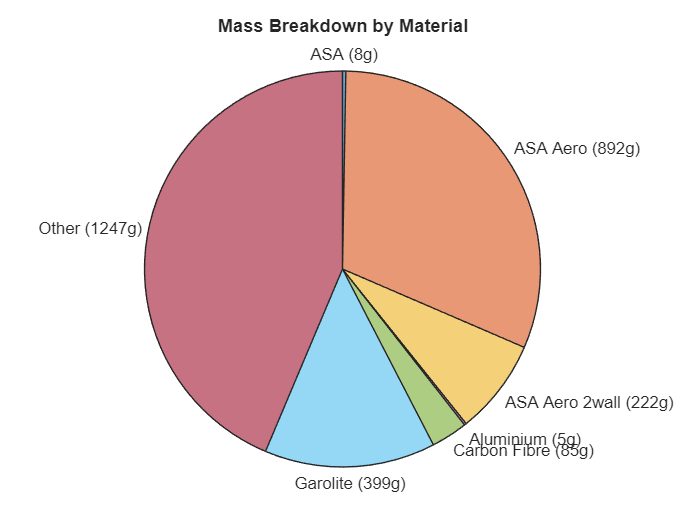

pieOf(a.Components.Material, a.Components.m, 'Mass Breakdown by Material');

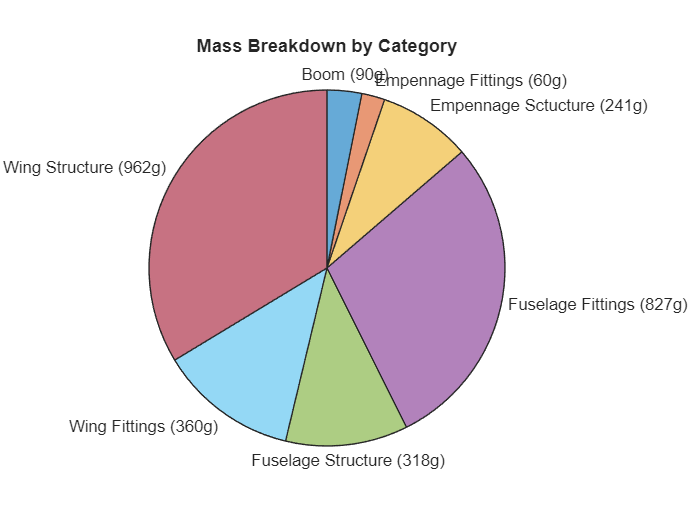

pieOf(a.Components.Category, a.Components.m, 'Mass Breakdown by Category');

## Stress Analysis

Wing

gravity = 9.80; %2G load
Lift = res(1)*gravity;
taumaxt = 3*Lift/(4*structure.Thickness*chord*0.12 ...
    )

taumaxt = 7.0005e+05

sigmamaxt = 3*(Lift*wingSpan)/(4*structure.Thickness*(chord*0.12)^2)

sigmamaxt = 4.6670e+07

sf = structure.YieldStress/sigmamaxt

sf = 6.0639